Plotting superquadrics

clear;
% Define parameters for 11 superquadrics (a,b,c,e1,e2,phi,psi,theta,h,k,l)
% params = {
%     [1.25, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0];
%     [2, 1, 2, 1, 1, pi/4, pi/4, pi/4, 4, 2, 2];
%     % [1, 2, 1, 0.5, 0.5, pi/3, pi/3, pi/3, -9, 0, -2];
%     % [1, 1, 2, 0.3, 0.4, pi/6, pi/6, pi/6, 5, -5, 5];
%     % [2, 3, 2, 1.5, 1.5, 0, pi/2, 0, -6, 7, -6];
%     % [1, 2.5, 1.5, 0.3, 0.5, pi/4, 0, pi/4, 5, 6.5, 3];
%     % [1.5, 1, 2, 1.5, 1.5, pi/3, pi/3, pi/3, -4, 2, 0];
%     % [2, 1.5, 3, 1, 0.5, pi/6, pi/6, pi/6, -9, -6, 3];
%     % [1.5, 1, 1.5, 0.5, 1, 0, pi/4, 0, 1, -4, -4];
%     % [1, 2, 2.5, 1.5, 0.3, pi/4, 0, pi/4, 0, 5, -2];
%     % [1.5, 2.5, 2, 1, 2, pi/3, pi/3, pi/3, -3, -4, 7]
% };
% 
% % Plot the superquadrics
% plot_multiple_superquadrics(params);

Closest points between two superquadrics and separating hyperplane

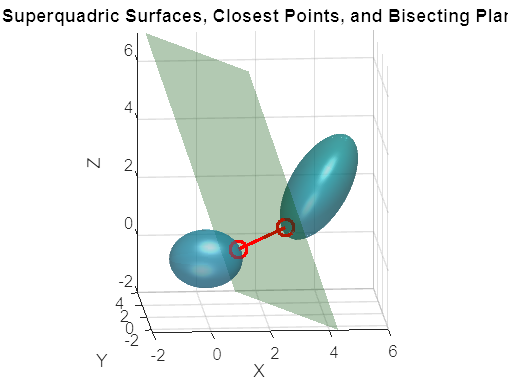

% Initialize parameters for the first superquadric
params1 = {[1.25, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0]};
params2 = {[2, 1, 2, 1, 1, pi/4, pi/4, pi/4, 4, 2, 2]};

% Plot the superquadrics and the closest points
%plotClosestPoints3D(params1, params2);
[u1_opt, v1_opt, u2_opt, v2_opt, min_distance, plane_eq] = find_closest_points(params1, params2);
hold off;

Plotting Voronoi diagram for superquadrics

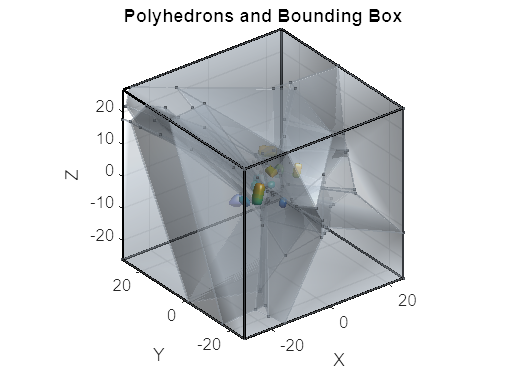

% Define parameters for 11 superquadrics (a,b,c,e1,e2,phi,psi,theta,h,k,l)
tic
params = {
    [1.25, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0];
    [2, 1, 2, 1, 1, pi/4, pi/4, pi/4, 4, 2, 2];
  [1, 2, 1, 0.5, 0.5, pi/3, pi/3, pi/3, -9, 0, -2];
     [1, 1, 2, 0.3, 0.4, pi/6, pi/6, pi/6, 5, -5, 5];
    [2, 3, 2, 1.5, 1.5, 0, pi/2, 0, -6, 7, -6];
    [1, 2.5, 1.5, 0.3, 0.5, pi/4, 0, pi/4, 5, 8, 5];
    [1.5, 1, 2, 1.5, 1.5, pi/3, pi/3, pi/3, -4, 2, 0];
    [2, 1.5, 3, 1, 0.5, pi/6, pi/6, pi/6, -9, -6, 3];
    [1.5, 1, 1.5, 0.5, 1, 0, pi/4, 0, 1, -4, -4];
    [1, 2, 2.5, 1.5, 0.3, pi/4, 0, pi/4, 0, 5, -2];
    [1.5, 2.5, 2, 1, 2, pi/3, pi/3, pi/3, -3, -4, 7]
};
% Plot the superquadrics
%plot_multiple_superquadrics(params);
[B_all, b_all, polyhedrons, bbox_min, bbox_max] = calculate_bisecting_planes_copy(params);

toc

Elapsed time is 5.215074 seconds.


Voronoi graph creation

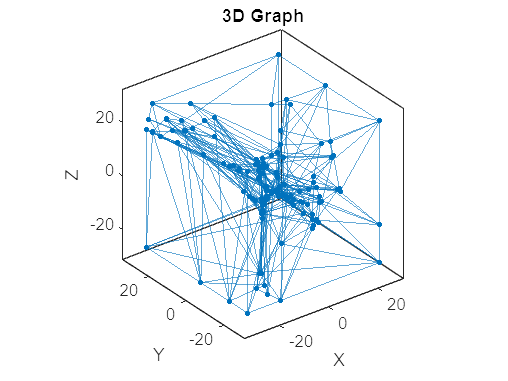

The graph is connected.


vertexGraph =   graph with properties:

    Edges: [477×2 table]
    Nodes: [159×4 table]


thresholdDistance = 0.5;
pointsPerFace = 3;
tic
vertexGraph = createVoronoiGraph(polyhedrons)%, ...

   % thresholdDistance);%,pointsPerFace);
toc

Elapsed time is 2.391322 seconds.


Shortest Path Calculation

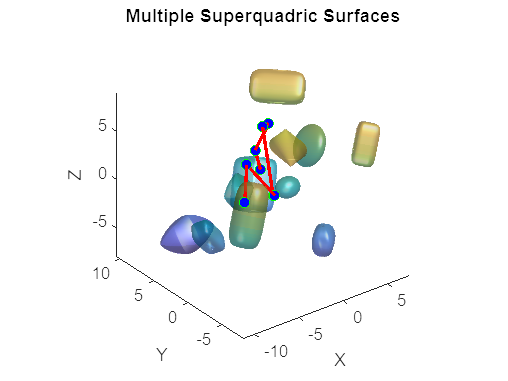

startPoint = [-11,-8,6];
endPoint = [0,4,0];
Copy_of_ShortestPath(vertexGraph, startPoint, endPoint,params)

## Path planning for extended robot

small_cuboid_params = [3, 2, 4, 0.1, 0.1, pi/6,pi/3,pi/12,0,0,0];
mm = [100,100];
s2 = SuperQuadrics({small_cuboid_params(1:3), small_cuboid_params(4:5)...
   ,[0,0],zeros(3,1), angle2quat(small_cuboid_params(6),small_cuboid_params(7)...
   ,small_cuboid_params(8)), mm});

'angle2quat' requires Aerospace Toolbox.

% Define parameters for 11 superquadrics (a,b,c,e1,e2,phi,psi,theta,h,k,l)
% params = {
%     [1.25, 1, 1, 1, 1, 0, 0, 0, 0, 0, -1];
%     [2, 1, 2, 1, 1, pi/4, pi/4, pi/4, 4, 2, 4];
%     [1, 2, 1, 0.5, 0.5, pi/3, pi/3, pi/3, -9, 0, -3];
%      [1, 1, 2, 0.6, 0.4, pi/6, pi/6, pi/6, 5, -5, 5];
% %     [2, 3, 2, 1.5, 1.5, 0, pi/2, 0, -6, 7, -6];
% %     [1, 2.5, 1.5, 0.3, 0.5, pi/4, 0, pi/4, 5, 8, 5];
% %     [1.5, 1, 2, 1.5, 1.5, pi/3, pi/3, pi/3, -4, 2, 0];
% %     [2, 1.5, 3, 1, 0.5, pi/6, pi/6, pi/6, -9, -6, 3];
% %     [1.5, 1, 1.5, 0.5, 1, 0, pi/4, 0, 1, -4, -4];
% %     [1, 2, 2.5, 1.5, 0.3, pi/4, 0, pi/4, 0, 5, -2];
% %     [1.5, 2.5, 2, 1, 1.9, pi/3, pi/3, pi/3, -3, -4, 7]
% };
params = {
    [randi([8, 11]), randi([8, 11]), randi([8, 11]), 1, 1, 0, 0, 0, 0, 0, -10];       % Superquadric 1
    [randi([8, 11]), randi([8, 11]), randi([8, 11]), 1, 1, pi/4, pi/4, pi/4, 15, 20, 15]; % Superquadric 2
    [randi([8, 11]), randi([8, 11]), randi([8, 11]), 0.5, 0.5, pi/3, pi/3, pi/3, -30, 0, -10]; % Superquadric 3
    [randi([8, 11]), randi([8, 11]), randi([8, 11]), 0.6, 0.4, pi/6, pi/6, pi/6, 25, -25, 25]; % Superquadric 4
    [randi([8, 11]), randi([8, 11]), randi([8, 11]), 1.5, 1.5, 0, pi/2, 0, -60, 35, -30]; % Superquadric 5
    [randi([8, 11]), randi([8, 11]), randi([8, 11]), 0.3, 0.5, pi/4, 0, pi/4, 45, 70, 50]; % Superquadric 6
    [randi([8, 11]), randi([8, 11]), randi([8, 11]), 1.5, 1.5, pi/3, pi/3, pi/3, -40, 20, 10]; % Superquadric 7
    [randi([8, 11]), randi([8, 11]), randi([8, 11]), 1, 0.5, pi/6, pi/6, pi/6, -90, -60, 30]; % Superquadric 8
    [randi([8, 11]), randi([8, 11]), randi([8, 11]), 0.5, 1, 0, pi/4, 0, 10, -40, -40]; % Superquadric 9
    [randi([8, 11]), randi([8, 11]), randi([8, 11]), 1.5, 0.3, pi/4, 0, pi/4, 0, 50, -20]; % Superquadric 10
    [randi([8, 11]), randi([8, 11]), randi([8, 11]), 1, 1.9, pi/3, pi/3, pi/3, -30, -40, 70] % Superquadric 11
};


% Initialize storage for Minkowski sums
minkowski_sums = cell(size(params, 1), 1);

% Compute Minkowski sums for each superquadric
for i = 1:size(params, 1)
    % Create Superquadric object
    s1 = SuperQuadrics({params{i}(1:3), params{i}(4:5), [0,0],...
    zeros(3,1), angle2quat(params{i}(6),params{i}(7)...
   ,params{i}(8)), mm});
    % Compute Minkowski sum
    M1 = quat2rotm(angle2quat(params{i}(6),params{i}(7)...
   ,params{i}(8)));M2=eye(3);
    minkowski_sums{i} = MinkSumClosedForm(s1, s2, M1, M2).GetMinkSumFromGradient(s1.GetGradientsCanonical());
    colsWithNaN = any(isnan(minkowski_sums{i}), 1);
    minkowski_sums{i}(:,colsWithNaN) = [];
end

% Fitting superquadrics onto the minkowski sums(x:(e1,e2,a,b,c,phi,theta,psi,h,k,l))
params_mink = cell((size(params)));
for i = 1:size(params,1)
    x = EMS(minkowski_sums{i},'OutlierRatio',0);
    params_mink{i}(1:3)  = x(3:5);
    params_mink{i}(4:5)  = x(1:2);
    params_mink{i}(6:8)  = x(6:8);
    params_mink{i}(9:11) = params{i}(9:11); 
end

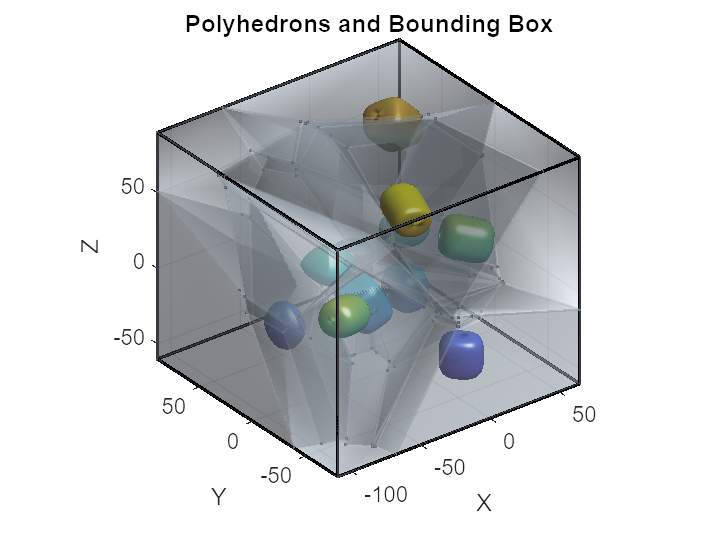

[B_all, b_all, polyhedrons, bbox_min, bbox_max] = calculate_bisecting_planes_copy(params_mink);

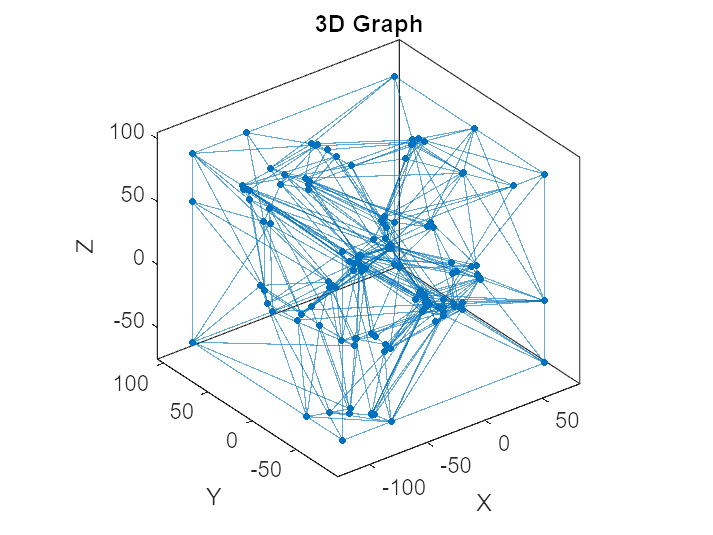

The graph is connected.


vertexGraph_mink = createVoronoiGraph(polyhedrons);

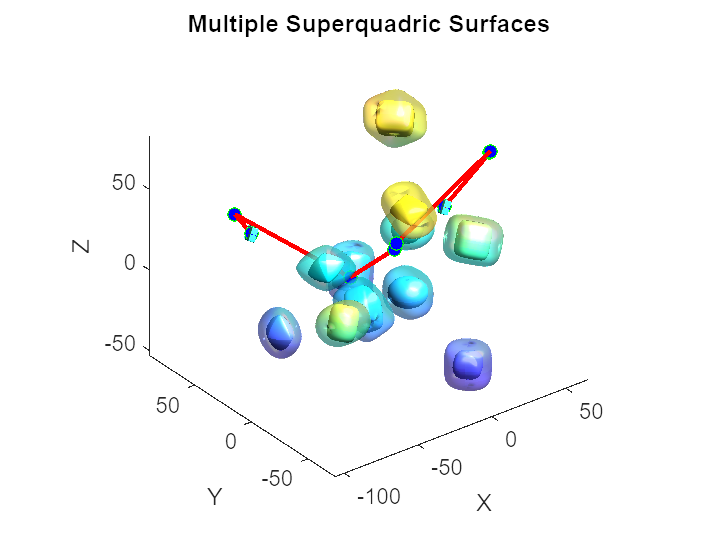

startPoint = [-60,60,20];
endPoint = [40,20,20];
Copy_of_ShortestPath(vertexGraph_mink, startPoint, endPoint,params_mink)
plot_multiple_superquadrics(params,0);
small_cuboid_params1 = small_cuboid_params;small_cuboid_params2=small_cuboid_params;
small_cuboid_params1(9:11) = startPoint;small_cuboid_params2(9:11) = endPoint;
plot_multiple_superquadrics({small_cuboid_params1,small_cuboid_params2},0);

% Compute Minkowski sums
mink_obj = MinkSumClosedForm(s1, s2, M1, M2);
m1 = s1.GetGradientsCanonical();
mink = mink_obj.GetMinkSumFromGradient(m1);

% Plot: Minkowski sums
figure; hold on; axis equal; axis off;
X = reshape(mink(1,:), mm);
Y = reshape(mink(2,:), mm);
Z = reshape(mink(3,:), mm);
surf(X, Y, Z, 'FaceColor', 'y',...
    'EdgeColor', 'none', 'FaceAlpha', 0.6);

% Plot s1
x1 = M1 * s1.GetPointsCanonical();
X = reshape(x1(1,:), mm);
Y = reshape(x1(2,:), mm);
Z = reshape(x1(3,:), mm);
surf(X, Y, Z, 'FaceColor', 'g',...
    'EdgeColor', 'none', 'FaceAlpha', 1);

% %Plot s2
% for i = 1:size(mink,2)/5:size(mink,2)
%     s2_touch = M2 * s2.GetPointsCanonical() + mink(:,i);
%     
%     X = reshape(s2_touch(1,:), mm);
%     Y = reshape(s2_touch(2,:), mm);
%     Z = reshape(s2_touch(3,:), mm);
%     surf(X, Y, Z, 'FaceColor', 'b',...
%         'EdgeColor', 'none', 'FaceAlpha', 1);
% end

lightangle(gca,45,30);
lighting gouraud;
% x = EMS(mink,'OutlierRatio',0.0001);
% showSuperquadrics(x, 'Color', [0 0 1], 'FaceAlpha', 0.7, 'Arclength', 0.05, 'Light', 1);
% hold off;